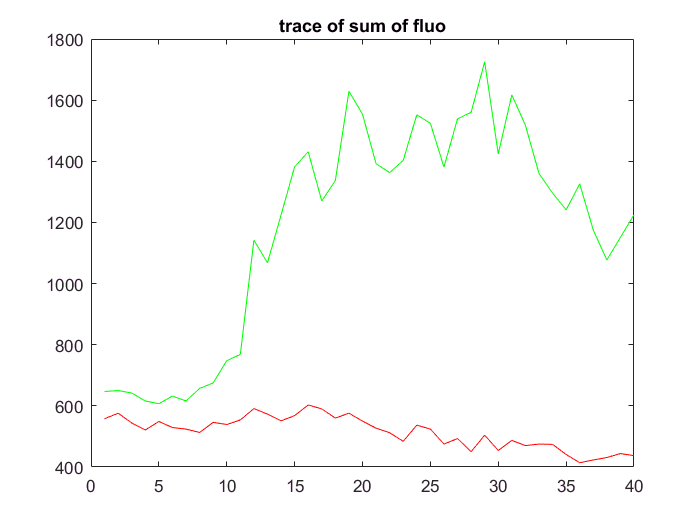

% plots actual traces
load('C:\Users\seanm\Desktop\garcia_lab_stuff\elong_search\dat\real_data\processed_data.mat');
i = 9;
data = preprocessed(i);

figure;
plot(data.greensum, 'g');
hold on
plot(data.redsum, 'r');
title('trace of sum of fluo');

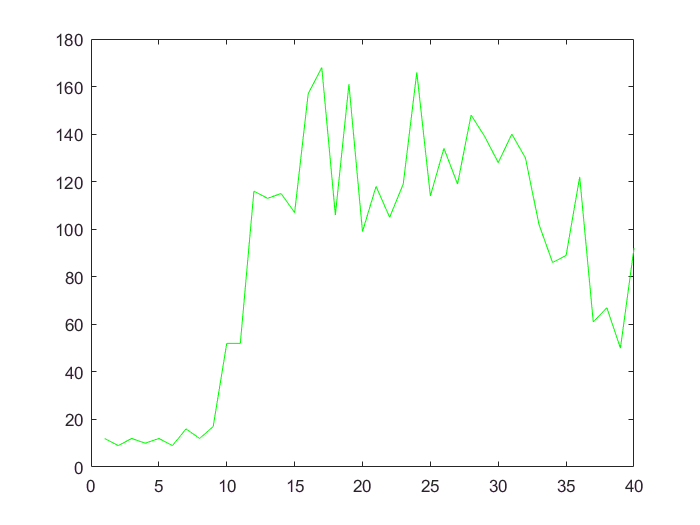


figure;
plot(data.greenmax, 'g');

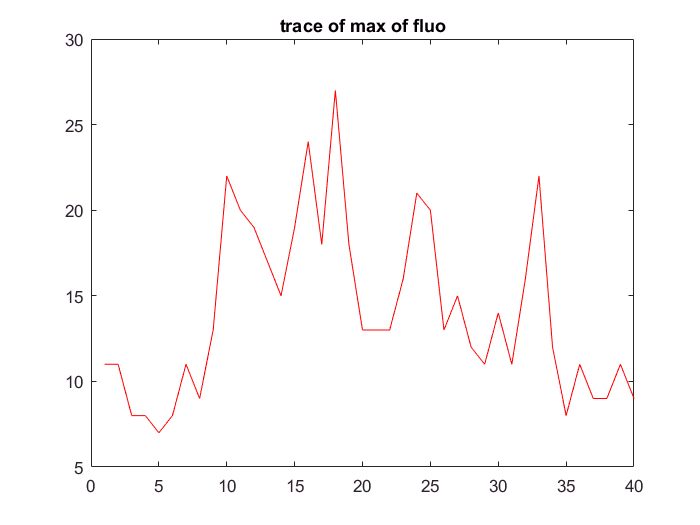

figure
plot(data.redmax, 'r');

title('trace of max of fluo');

% sets up variables for cross correlation on real data

max_delay = 25;
project = 'real data max';
trace1 = cell([1 length(preprocessed)]);
trace2 = cell([1 length(preprocessed)]);
for i = 1:length(preprocessed)
    trace1{i} = preprocessed(i).redmax;
    trace2{i} = preprocessed(i).greenmax;
end

Undefined function or variable 'cross_corr_analysis'.

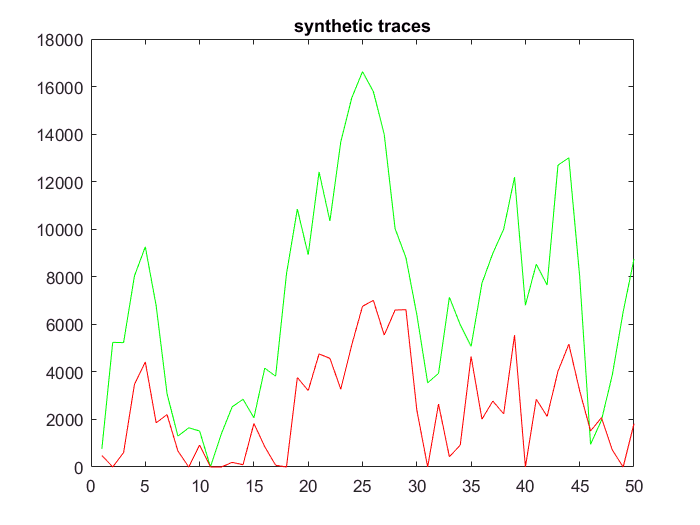

% plots synthetic data (manually add time delay)
tr = 1;
figure;
plot(data.fluo_data{1}{tr}, 'g');
hold on;
plot(data.fluo_data{2}{tr}, 'r');
title('synthetic traces');

% sets up variables for cross correlation on synthetic data

max_delay = 25;
project = 